% Parameters
R0 = 2.5;
n_days = 20;

% Transfer function H1(z)
numerator = [1,0];
denominator = [1, -R0];
H1 = tf(numerator, denominator)

H1 =
 
     s
  -------
  s - 2.5
 
Continuous-time transfer function.



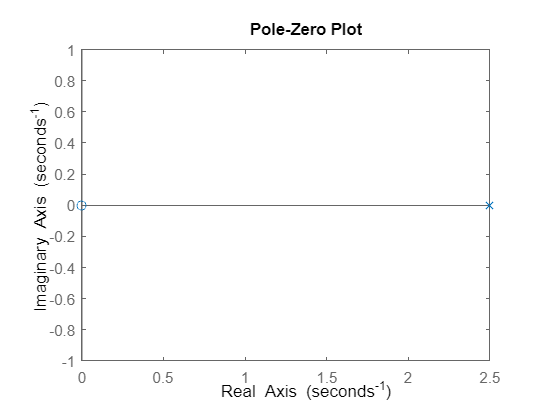


% Pole-Zero plot
figure;
pzmap(H1);
title('Pole-Zero Plot');

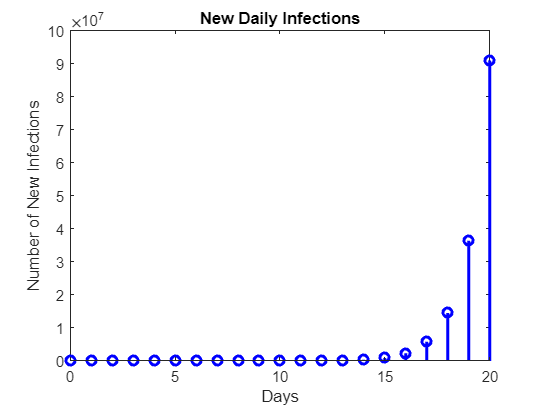


% Solve the difference equation
n = 0:n_days;
y = R0.^n;

% Plot new daily infections
figure;
stem(n, y, 'b', 'LineWidth', 2);
title('New Daily Infections');
xlabel('Days');
ylabel('Number of New Infections');


% Time to reach 1 million new daily infections
days_to_reach_million = log(1e6) / log(R0);
fprintf('Days to reach 1 million new daily infections: %.2f days\n', days_to_reach_million);

Days to reach 1 million new daily infections: 15.08 days


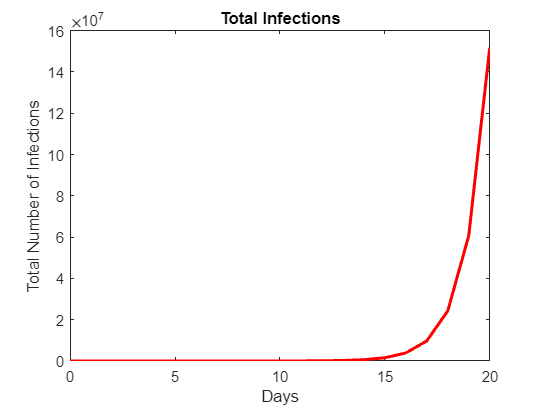


% Integrator filter
total_infections = cumsum(y);

% Plot total infections
figure;
plot(n, total_infections, 'r', 'LineWidth', 2);
title('Total Infections');
xlabel('Days');
ylabel('Total Number of Infections');